% initiation
maindir = 'D:\Call_Bergles_2021_CTSM\CTSM\';
addpath(genpath(maindir))
CTSM_PLM = calculatePLM;

Started processing for NTSR1.
Finished processing all NTSR1 traces.
Started processing for NXPH4.
Finished processing all NXPH4 traces.
Started processing for PO.
Finished processing all PO traces.
Started processing for PV.
Finished processing all PV traces.
Started processing for RBP4.
Finished processing all RBP4 traces.
Started processing for SOM.
Finished processing all SOM traces.
Started processing for VM.
Finished processing all VM traces.


## PLM comparison

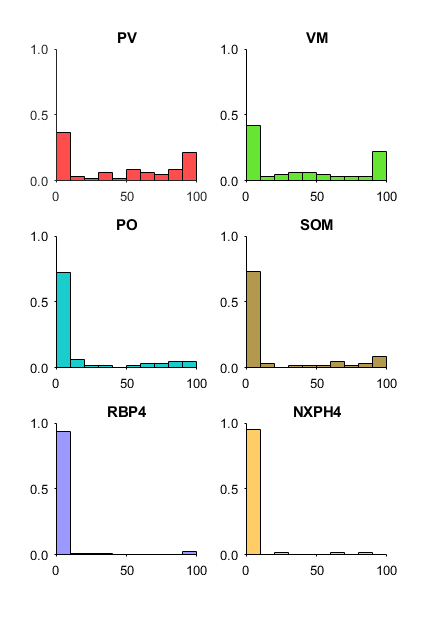

plotHisto(CTSM_PLM);

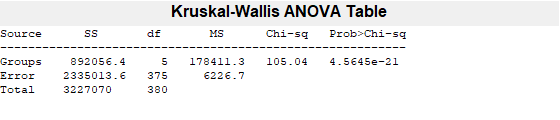

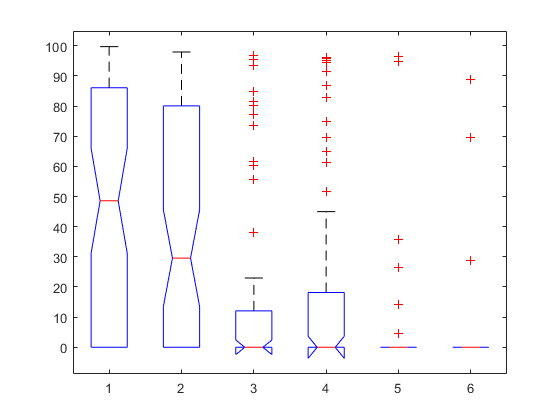

data = NaN(78,6);
axNames = {'PV','VM','PO','SOM','RBP4','NXPH4'};
for i = 1:length(axNames)
    data(1:length(CTSM_PLM.(axNames{i}).cmbdData),i) = CTSM_PLM.(axNames{i}).cmbdData;
end
[plm_p,plm_tbl,plm_stats] = kruskalwallis(data);

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


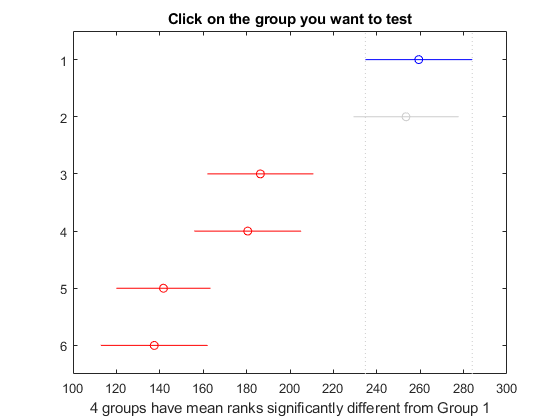

[plm_comparison] = multcompare(plm_stats,'CType','dunn-sidak');


plm_comparison = cellifycomp(plm_comparison,axNames);
csvdata = [plm_tbl; cell(1,6); plm_comparison];
writecell(csvdata,[maindir 'CTSMTableData.xls'],'Sheet','PLM')

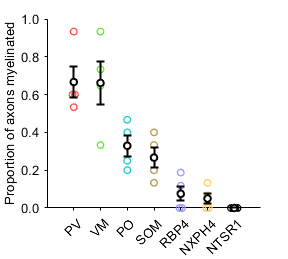

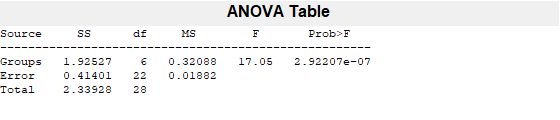

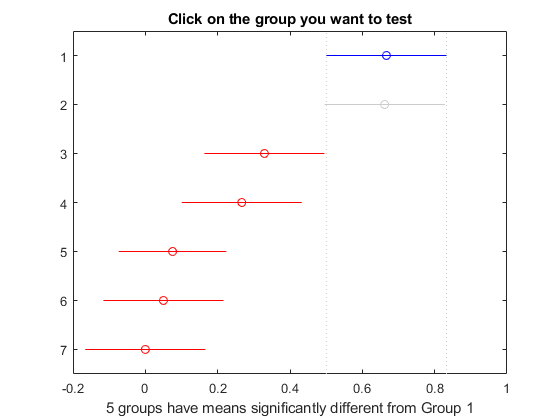

% proportion of axons myelinated
[propAvg,propSEM,propTbl,propmyel_comparison] = plotPropMyel(CTSM_PLM);

axNames = {'PV','VM','PO','SOM','RBP4','NXPH4','NTSR1'};
propmyel_comparison = cellifycomp(propmyel_comparison,axNames);
csvdata = [propTbl; cell(1,6); propmyel_comparison];
writecell(csvdata,[maindir 'CTSMTableData.xls'],'Sheet','PropMyel')

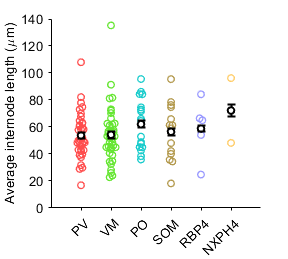

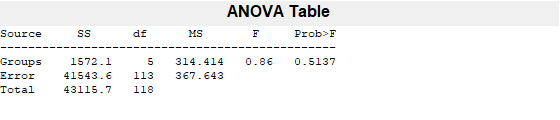

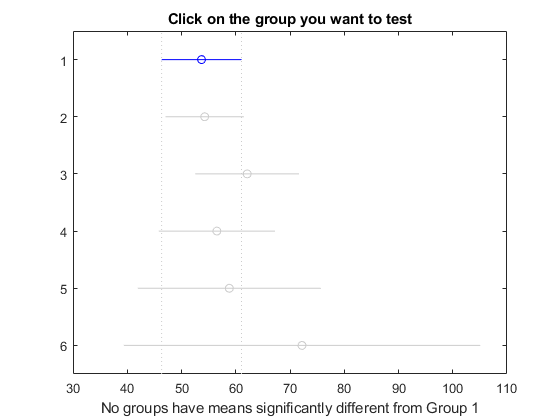

% average internode lengths
[int_p,int_tbl,int_stats,int_comparison] = plotIntLengths(CTSM_PLM); 

axNames = {'PV','VM','PO','SOM','RBP4','NXPH4'};
int_comparison = cellifycomp(int_comparison,axNames);
writecell(int_comparison,[maindir 'CTSMTableData.xls'],'Sheet','IntLengths')

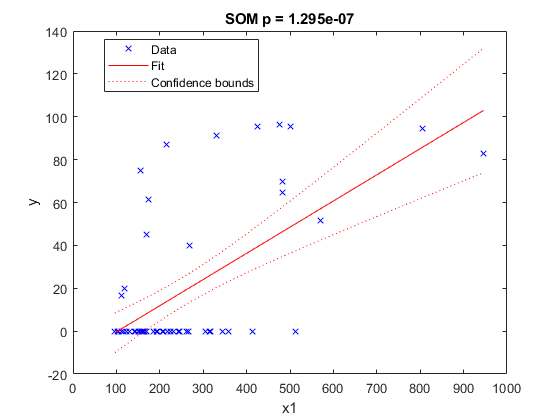

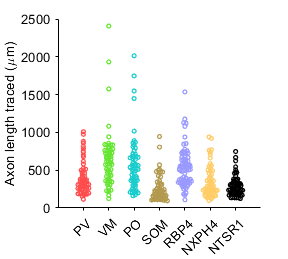

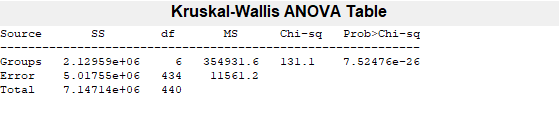

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


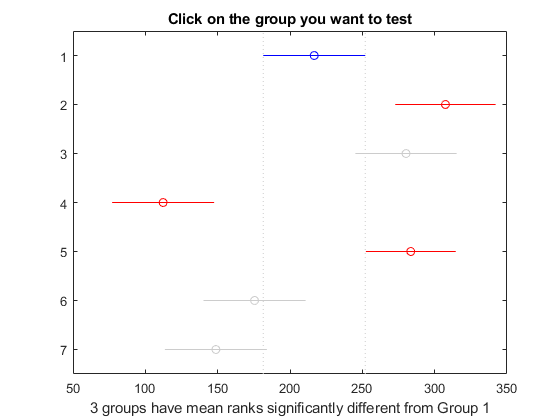

% average axon lengths 
[mdls,axon_p,axon_tbl,axon_stats,axon_comparison] = plotAxonLengths(CTSM_PLM);

axNames = {'PV','VM','PO','SOM','RBP4','NXPH4','NTSR1'};
axon_comparison = cellifycomp(axon_comparison,axNames);
writecell(axon_comparison,[maindir 'CTSMTableData.xls'],'Sheet','AxLengths')

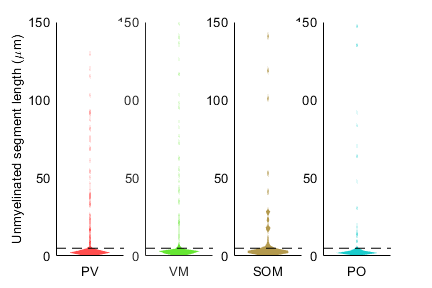

unmyelSegData = 1×8 cell array
    {1×127 double}    {1×64 double}    {1×204 double}    {1×77 double}    {1×75 double}    {1×21 double}    {1×46 double}    {1×21 double}


% distribution of unmyelinated segment lengths
unmyelSegData = plotUnmyelSegsViolin

## Areal comparison

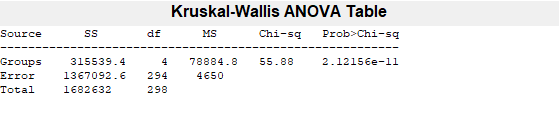

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


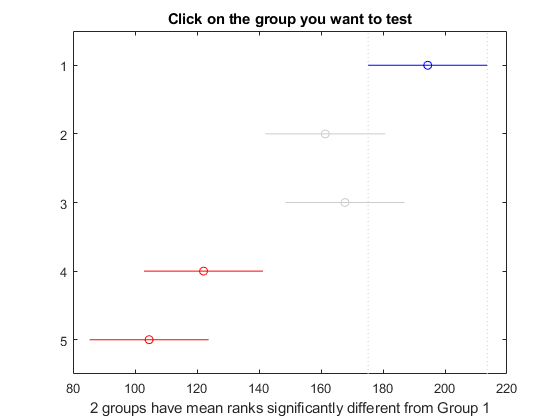

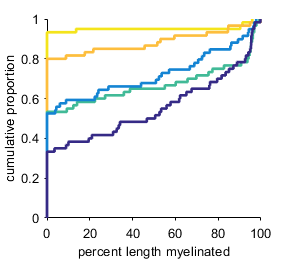

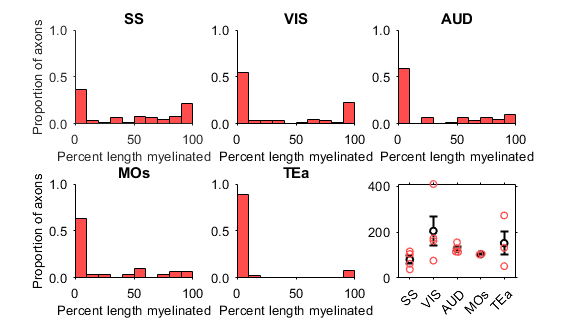

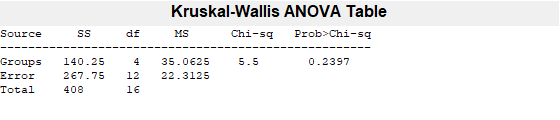

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


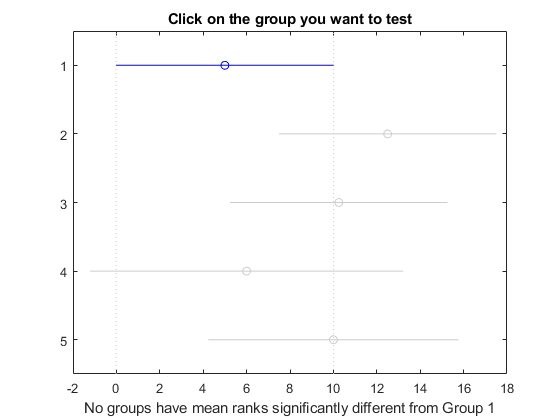

[areal_PLM,areal_ps,areal_tbls,areal_stats,areal_comparisons,gNames] = analyzeArealPLM(CTSM_PLM);

% write stats to csv
datasource1 = [{'Distributions'} cell(1,5)];
datasource2 = [{'Scaled prevalence'} cell(1,5)];
xNames = {'SS','VIS','AUD','MOs','TEa'};
comp1 = cellifycomp(areal_comparisons{1},xNames);
comp2 = cellifycomp(areal_comparisons{2},xNames);
csvdata = [datasource1; areal_tbls{1}; cell(1,6); comp1; cell(1,6);...
          datasource2; areal_tbls{2}; cell(1,6); comp2];
writecell(csvdata,[maindir 'CTSMTableData.xls'],'Sheet','arealPLM')

## Diameter analysis

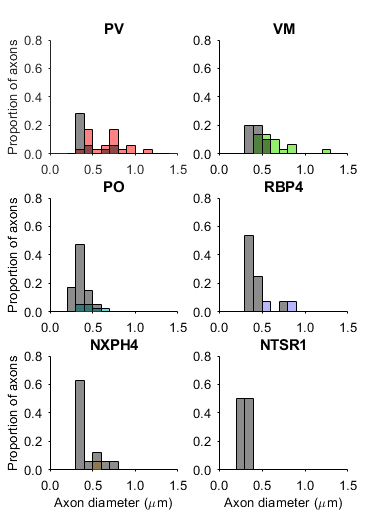

plotIndiv_MyelVDiam

1. Removing diam:type, Deviance = 89.132, Chi2Stat = 6.9162, PValue = 0.22694


glm = Generalized linear regression model:
    probit(PLM) ~ 1 + diam + type
    Distribution = Binomial

Estimated Coefficients:
                   Estimate        SE           tStat         pValue  
                   ________    __________    ___________    __________

    (Intercept)     -3.0442        0.5813        -5.2369    1.6332e-07
    diam              5.836        1.0337         5.6458    1.6439e-08
    type_NTSR1      -15.215    2.5737e+06    -5.9117e-06             1
    type_NXPH4      -1.4699       0.64974        -2.2623      0.023678
    type_RBP4       -1.0141       0.45694        -2.2194      0.026458
    type_PO        -0.48084       0.38935         -1.235       0.21683
    type_VM        0.046686       0.36725     

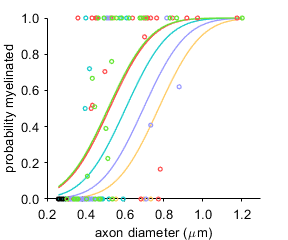

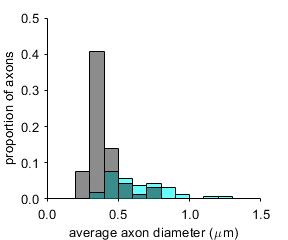

p = 8.9925e-14

ks2stat = 0.6693

[glm,diamP,diamks2stat] = plotMyelVDiam;

writetable(glm.Coefficients,[maindir 'CTSMTableData.xls'],'Sheet','DiamGLM',"WriteRowNames",true)

function comp = cellifycomp(comp,axNames)
comp = num2cell(comp);
compcc = comp;
for g = 1:length(axNames)
    idx = cellfun(@(c) c==g,compcc(:,1:2),'UniformOutput',false);
    comp(cell2mat(idx)) = axNames(g);
end
complabels = {'samp1' 'samp2' 'lCI' 'estimate' 'uCI' 'p'};
comp = [complabels; comp];
end